%Parameters
   
         Ro = 2.09;
  sigma     = 0.0345;
  
gamma_asym  = 0.01;
 gamma_sym  = 0.109;
gamma_sev_r = 0.0001;
gamma_sev_d = 0.0001;
  epsilon   = 0.2;
  
 beta_asym  = Ro*(gamma_asym);
 beta_sym   = Ro*(gamma_sym);
 beta_sev   = Ro*(gamma_sev_r + gamma_sev_d);
      N     = 49650000;
      
%initial contitions      
     I0     = 5;
     S0     = N - I0;
     E0     = 0;

     R0     = 0;
     D0     = 0;

%Reading data
DATA = readtable("src\Casos_positivos_de_COVID-19_en_Colombia.csv");

dates = rmmissing(datetime(DATA.FechaDiagnostico, 'InputFormat', 'yyyy-MM-dd''T''hh:mm:ss.S' ));
end_model_date = datetime('25-12-2021', "InputFormat", 'dd-MM-yyyy');
dates = dates(1):end_model_date;
n = 1:length(dates);

[deaths, death_dates] = groupcounts(rmmissing(datetime(DATA.FechaDeMuerte, 'InputFormat', 'yyyy-MM-dd''T''hh:mm:ss.S' )));

[recovered, recovered_dates] = groupcounts(rmmissing(datetime(DATA.FechaRecuperado, 'InputFormat', 'yyyy-MM-dd''T''hh:mm:ss.S' )));

[infected_count, type] = groupcounts(DATA.Estado);

infected_asym_total = infected_count(1);
infected_sym_total = sum(infected_count(3:5)); 
infected_sev_total = infected_count(3);
deaths_total = infected_count(2);

    %parameters
  eta    = infected_asym_total / (infected_sym_total + infected_asym_total);
  nu     =  infected_sev_total / infected_sym_total;

  %initial conditions
      I_asym0 = eta*I0;
     I_sym0 = (1 - eta)*(1 - nu)*I0;
     I_sev0 = (1 - eta)*nu*I0;


w_deaths = polyfit(1:length(deaths), log(deaths), 1);

reg_deaths = exp(w_deaths(2))*exp(w_deaths(1)*(1:length(deaths)));


w_reco = polyfit(1:length(recovered), log(recovered), 1);

reg_reco = exp(w_reco(2))*exp(w_reco(1)*(1:length(recovered)));

state = DATA.Estado;
noti_dates = rmmissing(datetime(DATA.FechaDiagnostico, 'InputFormat', 'yyyy-MM-dd''T''hh:mm:ss.S' ));

asym_dates = [noti_dates(1)];
sym_dates = [noti_dates(1)];
sev_dates = [noti_dates(1)];

j = 2;
for k = 2:length(state)
    if strcmp(state(k, 1), type(3, 1))
        sev_dates(j, 1) = noti_dates(k, 1);
        j = j + 1;
    end
end

j = 2;
for k = 2:length(state)
    if strcmp(state(k, 1), type(1, 1))
        asym_dates(j, 1) = noti_dates(k, 1);
        j = j + 1;
    end
end

[sev, sev_dates] = groupcounts(rmmissing(sev_dates));
[asym, asym_dates] = groupcounts(rmmissing(asym_dates));


w_asym = polyfit(1:length(asym), log(asym), 1);

reg_asym = exp(w_asym(2))*exp(w_asym(1)*(1:length(asym)));

w_sev = polyfit(1:length(sev), log(sev), 1);

reg_sev = exp(w_sev(2))*exp(w_sev(1)*(1:length(sev)));

[n, X] = ode45(@F, n, [S0; E0; I_asym0; I_sym0; I_sev0; R0; D0]);

model_asym = X(:, 3)';
model_sym = X(:, 4)';
model_sev = X(:, 5)';

model_recovered = X(:, 6)';
model_deaths    = X(:, 7)';

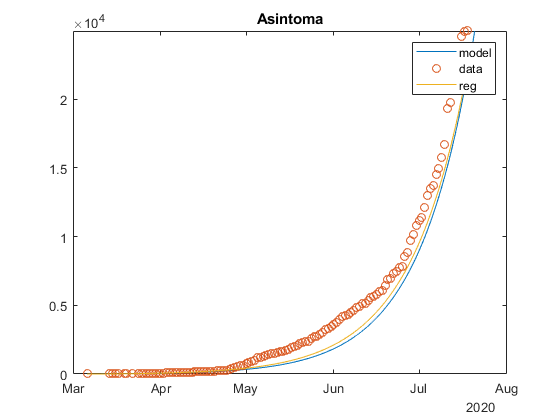

figure
plot(dates, cumulative(model_asym));
hold on
plot(asym_dates, cumulative(asym), 'o');
title('Asintoma')
plot(asym_dates, cumulative(reg_asym))
ylim([0 max(cumulative(asym))])
legend('model', 'data', 'reg')

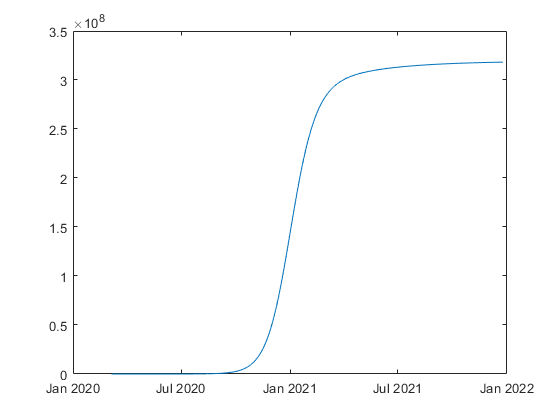


figure
plot(dates, cumulative(model_sym));

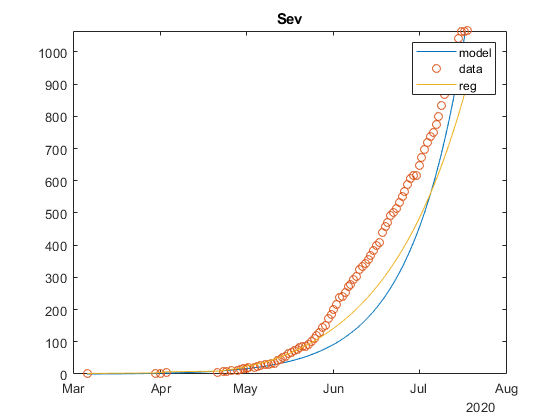

figure
plot(dates, cumulative(model_sev));
title('Sev amulative curves')
hold on
plot(sev_dates, cumulative(sev), 'o');
title('Sev')
plot(sev_dates, cumulative(reg_sev));
ylim([0 max(cumulative(sev))])
legend('model', 'data', 'reg')

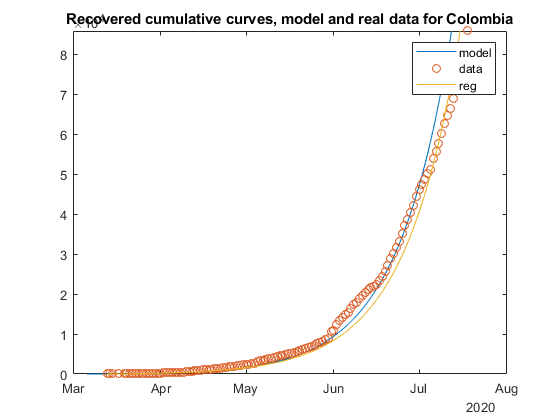


figure
plot(dates, cumulative(model_recovered))
hold on
plot(recovered_dates, cumulative(recovered), 'o')
hold on
plot(recovered_dates, cumulative(reg_reco))

legend('model', 'data', 'reg')
title('Recovered cumulative curves, model and real data for Colombia')
ylim([0 max(cumulative(recovered))])

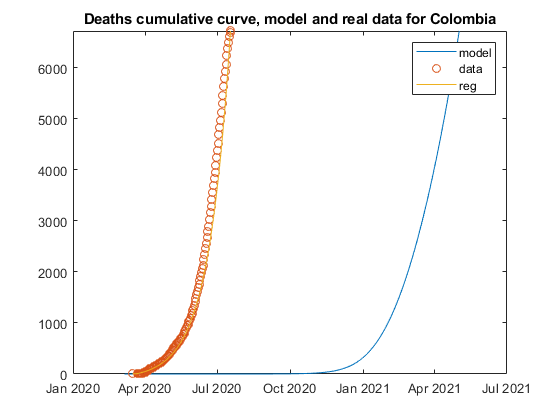


figure
plot(dates, cumulative(model_deaths));
hold on
plot(death_dates, cumulative(deaths), 'o')
hold on
plot(death_dates, cumulative(reg_deaths))

legend('model', 'data', 'reg')
title('Deaths cumulative curve, model and real data for Colombia');
ylim([0 max(cumulative(deaths))])

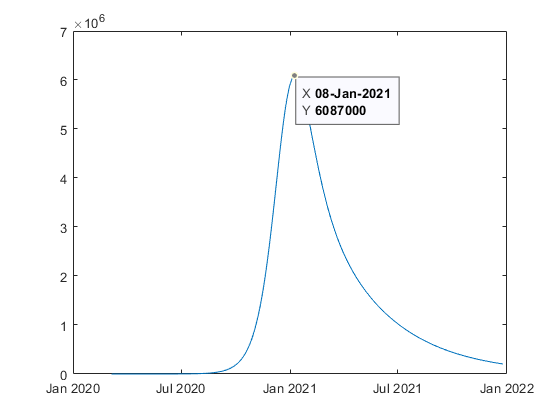

figure
plot(dates, model_sym + model_asym);

function y = cumulative(x)
    y = zeros(size(x));
    y(1) = x(1);
    for k = 2 : length(x)
       y(k) = x(k) + y(k-1);
    end
end


function dX = F(t, X)

%loading parameters
 eta = evalin('base', 'eta'); nu = evalin('base', 'nu'); sigma = evalin('base', 'sigma');
 beta_asym = evalin('base', 'beta_asym'); beta_sym = evalin('base', 'beta_sym'); beta_sev = evalin('base', 'beta_sev');
 gamma_asym = evalin('base', 'gamma_asym'); gamma_sym = evalin('base', 'gamma_sym');
 gamma_sev_r = evalin('base', 'gamma_sev_r'); gamma_sev_d = evalin('base', 'gamma_sev_d'); 
 epsilon = evalin('base', 'epsilon'); N = evalin('base', 'N');    
    
    S = X(1); E = X(2); I_asym = X(3); I_sym  = X(4);
    I_sev = X(5); R = X(6); D = X(7);
    
    dX = [-(beta_asym*I_asym + beta_sym*I_sym + beta_sev*I_sev).*S/N;...
        
           (beta_asym*I_asym + beta_sym*I_sym + beta_sev*I_sev).*S/N - epsilon*E;...
           
           eta*epsilon*E - gamma_asym*I_asym;...
           
           (1 - eta)*(1 - nu)*epsilon*E - gamma_sym*I_sym;...
           
           (1 - eta)*nu*epsilon*E - ((1 - sigma)*gamma_sev_r + sigma*gamma_sev_d)*I_sev;... %TODO: here
           
           gamma_asym*I_asym + gamma_sym*I_sym + (1 - sigma)*gamma_sev_r*I_sev;...
           
           sigma*gamma_sev_d*I_sev
           
           ];
end
